# Coordinate systems

The representation of the eye and the scene in the model code makes use of two different coordinate frames. Rendered images of the eye have yet another coordinate frame. This script creates a labeled 3D plot that illustrates these frames and their relationship.

A right eye is illustrated.

% Get the default sceneGeometry
sceneGeometry = createSceneGeometry();

## Eye coordinate space

Position relative to the anterior surface of the eye, in units of mm. More precisely, the *p1* axis is the longitudinal axis of the eye, which itself is an axis of the ellipsoidal vitreous chamber. The *p2* and *p3* axes roughly correspond to the horizontal and vertical meridians, respectively. The origin corresponds to the location of the apex of the *unrotated* cornea front surface ellipsoid.

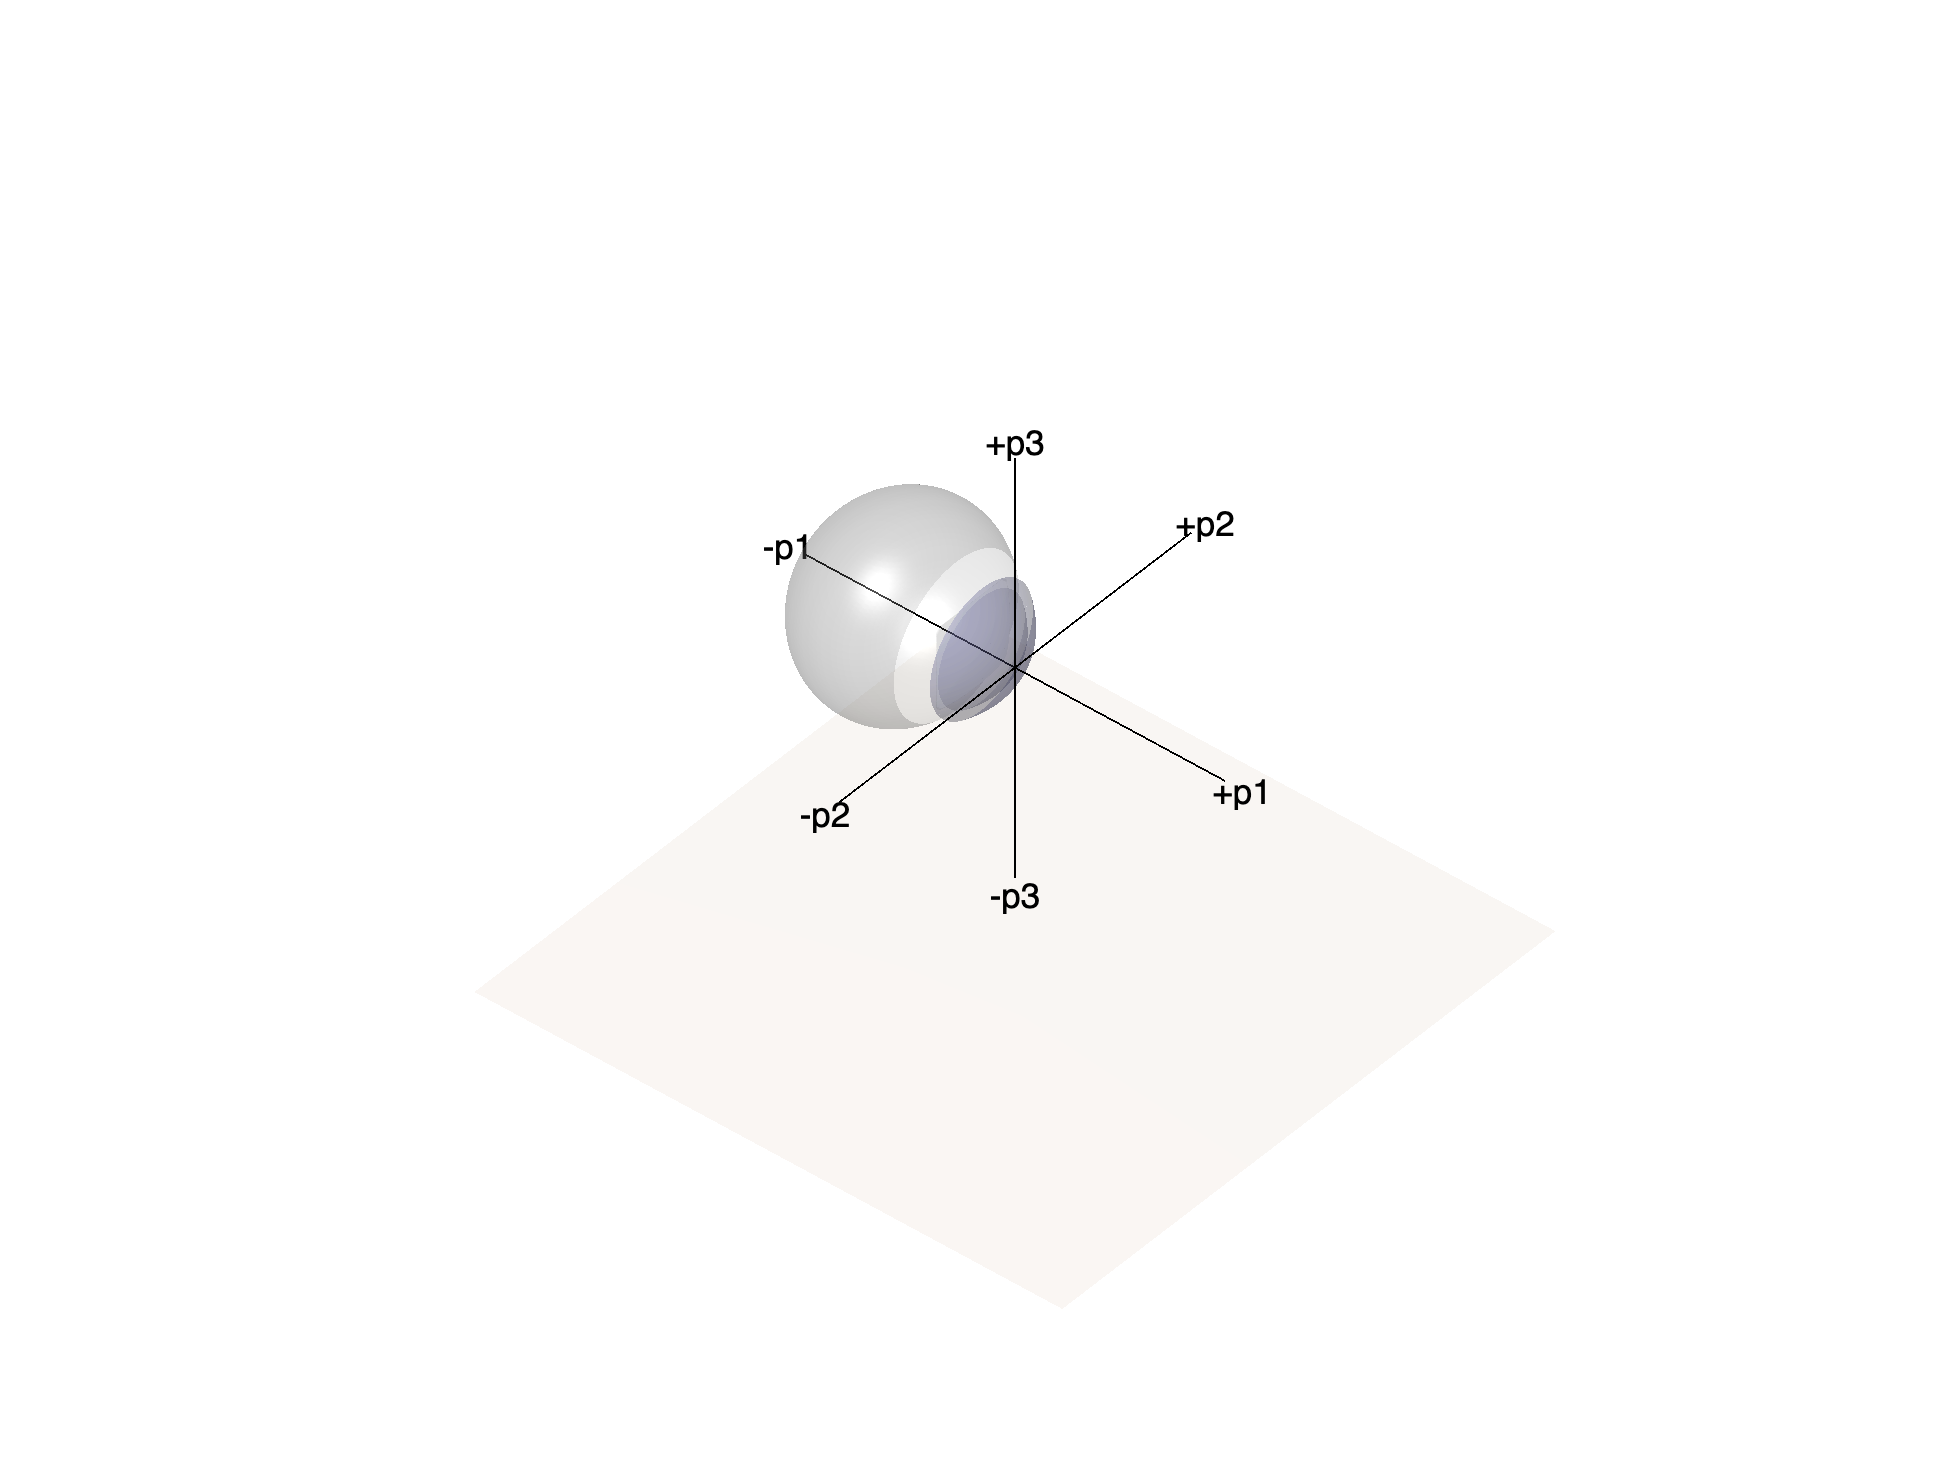

% Prepare a figure
figure('Name','Eye coordinates')

% Add the eye
plotOpticalSystem(sceneGeometry,'newFigure',false,'surfaceAlpha',0.4);

% Add axis lines for the eye coordinate system
plot3([-25 25],[0 0],[0 0],'-k')
plot3([0 0],[-25 25],[0 0],'-k')
plot3([0 0],[0 0],[-25 25],'-k')

% Add end-axis labels
text(-27,0,0,'-p1','HorizontalAlignment','center'); text(+27,0,0,'+p1','HorizontalAlignment','center');
text(0,-27,0,'-p2','HorizontalAlignment','center'); text(0,+27,0,'+p2','HorizontalAlignment','center');
text(0,0,-27,'-p3','HorizontalAlignment','center'); text(0,0,+27,'+p3','HorizontalAlignment','center');

% Indicate floor
f = fill3([-35 35 -35 35],[35 35 -35 -35],[-35 -35 -35 -35],[0.7 0.4 0.1],'LineStyle','none');
set(f,'facealpha',0.05)
f = fill3([-35 -35 35 35],[35 -35 35 -35],[-35 -35 -35 -35],[0.7 0.4 0.1],'LineStyle','none');
set(f,'facealpha',0.05)
axis off

## World coordinate space

Positions relative to the front surface of the eye, in units of mm. The *z* axis corresponds to the longitudinal axis of the eye, when the eye is in *primary position*. The primary position is the rotational state of the eye for which torsion is zero, and for which every eye movement consistent with Listing's Law will result in an eye pose for which torsion is also zero. In practice, this corresponds to the subject comfortably viewing a straight-ahead target in "neutral" gaze. The *x* and *y* axes roughly correspond to the horizontal and vertical meridians, respectively.

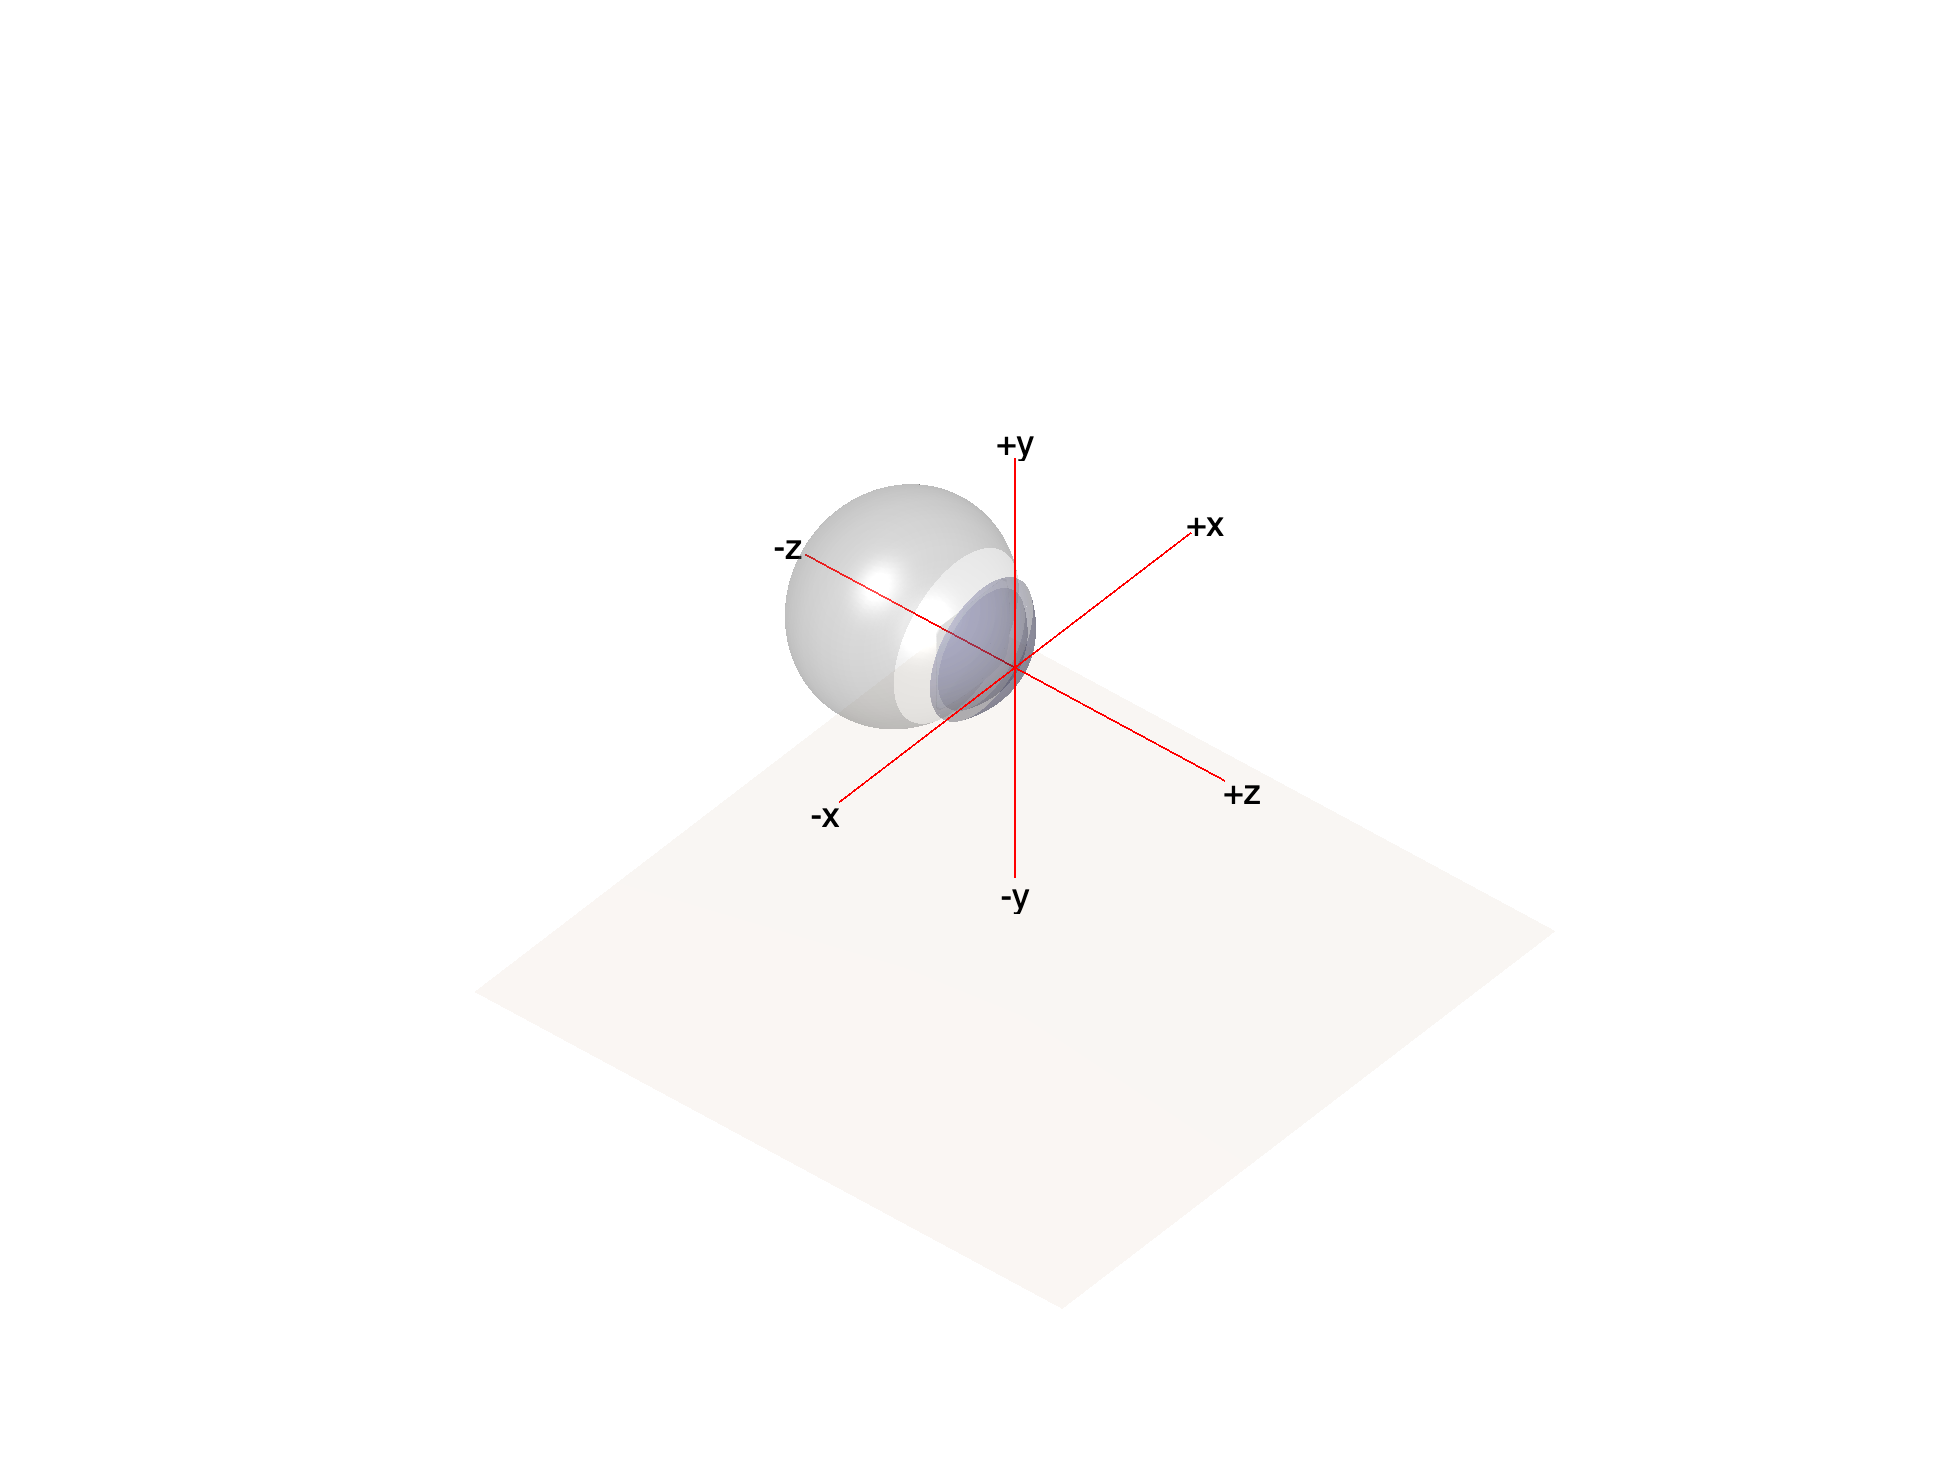

% Prepare a figure
figure('Name','World coordinates')

% Add the eye
plotOpticalSystem(sceneGeometry,'newFigure',false,'surfaceAlpha',0.4);

% Add axis lines for the eyeWorld space
plot3([-25 25],[0 0],[0 0],'-r')
plot3([0 0],[-25 25],[0 0],'-r')
plot3([0 0],[0 0],[-25 25],'-r')

% Add end-axis labels
text(-27,0,0,'-z','HorizontalAlignment','center'); text(+27,0,0,'+z','HorizontalAlignment','center');
text(0,-27,0,'-x','HorizontalAlignment','center'); text(0,+27,0,'+x','HorizontalAlignment','center');
text(0,0,-27,'-y','HorizontalAlignment','center'); text(0,0,+27,'+y','HorizontalAlignment','center');

% Indicate floor
f = fill3([-35 35 -35 35],[35 35 -35 -35],[-35 -35 -35 -35],[0.7 0.4 0.1],'LineStyle','none');
set(f,'facealpha',0.05)
f = fill3([-35 -35 35 35],[35 -35 35 -35],[-35 -35 -35 -35],[0.7 0.4 0.1],'LineStyle','none');
set(f,'facealpha',0.05)
axis off

## Eye rotations

Eye rotation in the model is implemented using Fick rotation angles. This allows for separate rotation centers for horizontal (azimuthal) and vertical (elevation) eye rotations. The eye has zero rotation in all directions when it is in primary position. Note that the fixation axis of the eye differs from the longitudal axis of the eye (as the fovea is not positioned at the retinal vertex). So, fixation of a target that is located directly in front of the eye along the *z* world axis will require non-zero rotation.

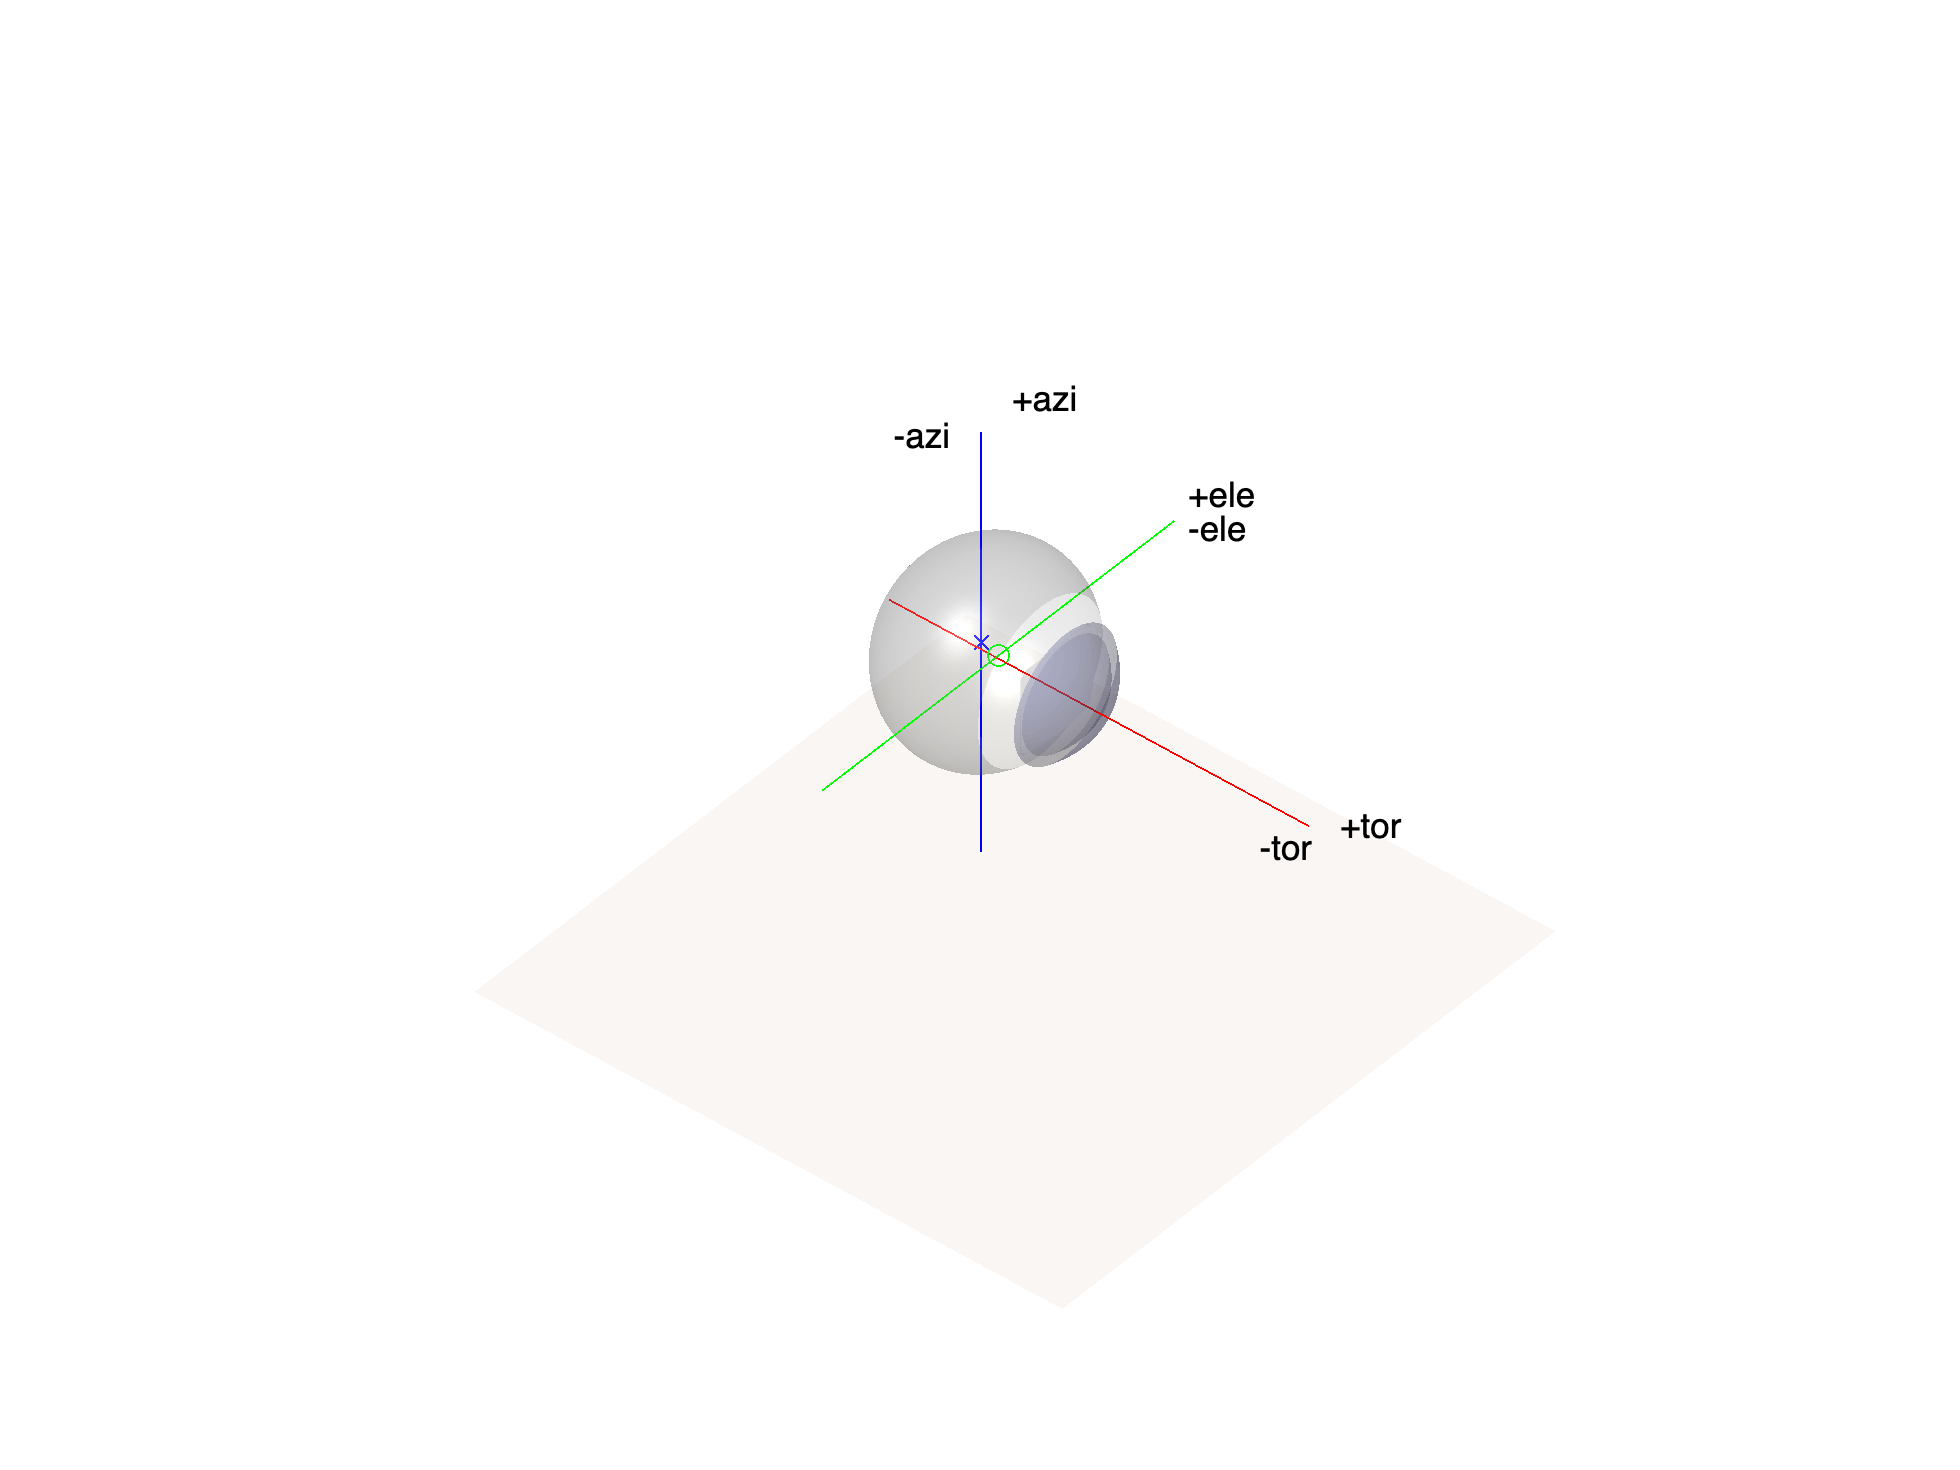

% Prepare a figure
figure('Name','Eye rotations')

% Add the eye
plotOpticalSystem(sceneGeometry,'newFigure',false,'surfaceAlpha',0.4);

% Obtain the rotation centers
azi = sceneGeometry.eye.rotationCenters.azi;
ele = sceneGeometry.eye.rotationCenters.ele;

% Add axis lines for the eyeWorld space
plot3([-25 25],[0 0],[0 0],'-r')
plot3([ele(1) ele(1)],[-25 25],[ele(3) ele(3)],'-g')
plot3(ele(1),ele(2),ele(3),'og');
plot3([azi(1) azi(1)],[azi(2) azi(2)],[-25 25],'-b')
plot3(azi(1),azi(2),azi(3),'xb')

% Add end-axis labels
text(+27,-2,0,'-tor','HorizontalAlignment','right'); text(+27,+2,0,'+tor','HorizontalAlignment','left');
text(ele(1),+27,ele(3)-2,'-ele','HorizontalAlignment','left'); text(ele(1),+27,ele(3)+2,'+ele','HorizontalAlignment','left');
text(azi(1)-2,azi(2)-2,+27-2,'-azi','HorizontalAlignment','right'); text(azi(1)+2,azi(2)+2,+27+2,'+azi','HorizontalAlignment','left');

% Indicate floor
f = fill3([-45 25 -45 25],[35 35 -35 -35],[-35 -35 -35 -35],[0.7 0.4 0.1],'LineStyle','none');
set(f,'facealpha',0.05)
f = fill3([-45 -45 25 25],[35 -35 35 -35],[-35 -35 -35 -35],[0.7 0.4 0.1],'LineStyle','none');
set(f,'facealpha',0.05)
axis off

## Image coordinate space

units of pixels

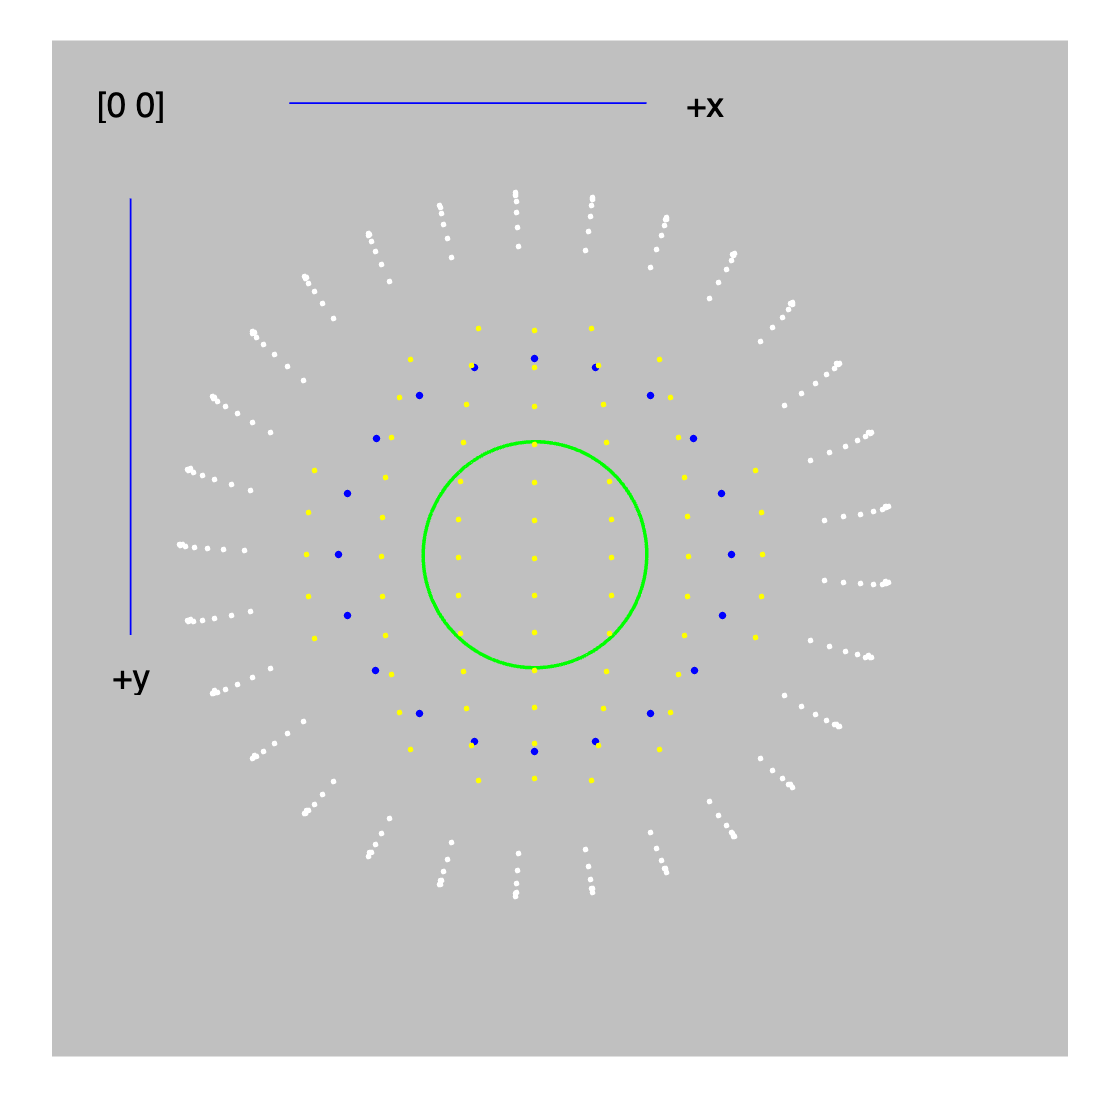

% Prepare a figure
figure('Name','Image coordinates')

% Add the eye
imageSizeX = sceneGeometry.cameraIntrinsic.sensorResolution(1);
imageSizeY = sceneGeometry.cameraIntrinsic.sensorResolution(2);
backgroundImage = zeros(imageSizeX,imageSizeX)+0.75;
imshow(backgroundImage,[], 'Border', 'tight');
hold on

% Translate the camera up a bit so that the rendered eye is drawn in the
% middle of the frame
sceneGeometry.cameraPosition.translation(2)=4;

% Render the eye
backgroundImage = zeros(imageSizeY,imageSizeX)+0.75;
eyePose = [0 0 0 3];
renderEyePose(eyePose, sceneGeometry,...
    'newFigure',false,...
    'modelEyeLabelNames', {'retina' 'irisPerimeter' 'pupilEllipse' 'cornea'},...
	'modelEyePlotColors', {'.w' 'ob' '-g' '.y'},...
	'modelEyeSymbolSizeScaler',0.5);

% Add some coordinate plots
hold on
text(50,40,'[0 0]','HorizontalAlignment','center');
text(400,40,'+x','HorizontalAlignment','left');
text(50,400,'+y','HorizontalAlignment','center');
plot([150 375],[40 40],'-b')
plot([50 50],[100 375],'-b')
ylim([-25 680.5]);